Fi = 1e3

Fi = 1000

Fs = 1e9

Fs = 1.0000e+09

Tstop = 0.02

Tstop = 0.0200

mdl = "class_d"

mdl = "class_d"

simin = Simulink.SimulationInput(mdl)

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



simin = setModelParameter(simin, ...
    "StopTime", string(Tstop))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''


input = strcat(mdl, "/Sine Wave")

input = "class_d/Sine Wave"

simin = setBlockParameter(simin, input, "Frequency", string(2*pi*Fi))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×1 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



output = strcat(mdl, "/Sampled Output")

output = "class_d/Sampled Output"

simin = setBlockParameter(simin, output, "SampleTime", string(1/Fs))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×2 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



out = sim(simin)

### Building the Accelerator target for model: class_d
### Successfully built the Accelerator target for model: class_d

Build Summary

Top model accelerator targets:

Model    Build Reason                          Status                        Build Duration
class_d  Accelerator MEX file is out of date.  Code generated and compiled.  0h 0m 4.3151s 

1 of 1 models built (0 models already up to date)
Build duration: 0h 0m 4.4328s


out =   Simulink.SimulationOutput:

             continuous: [1x1 struct] 
               discrete: [20000001x1 double] 
                   tout: [20086434x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


timeseries = get(out, "continuous")

timeseries = struct with fields:
         time: [20086434×1 double]
      signals: [1×1 struct]
    blockName: 'class_d/Continuous Output'


sampled = get(out, "discrete")

sampled =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


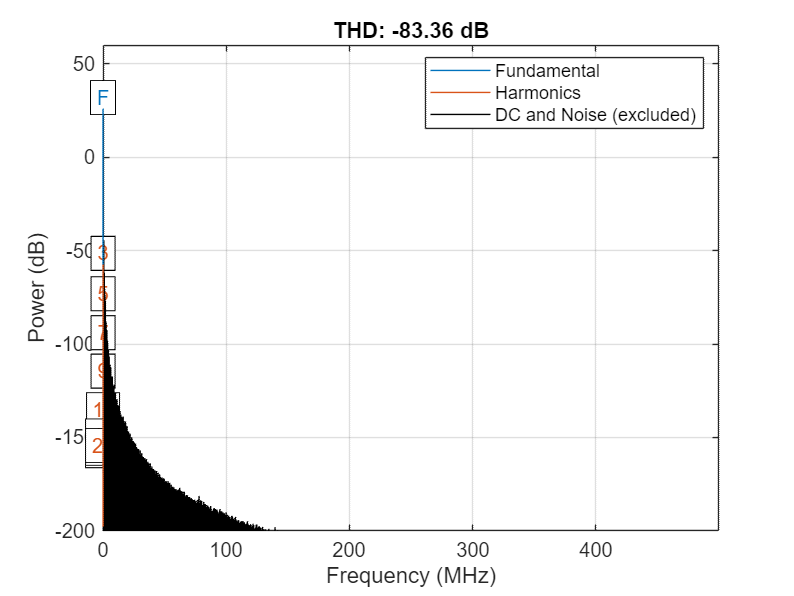

ans = -83.3603

thd(sampled,Fs,20)